# This script shows the targeted and untargeted adversarial example on googlenet

In order to perform a targeted attack, the fast gradient sign method (FGSM) has been employed and the basic iterative method (BIM) has been used for untargted attack.

**This Section loads the network and the image**

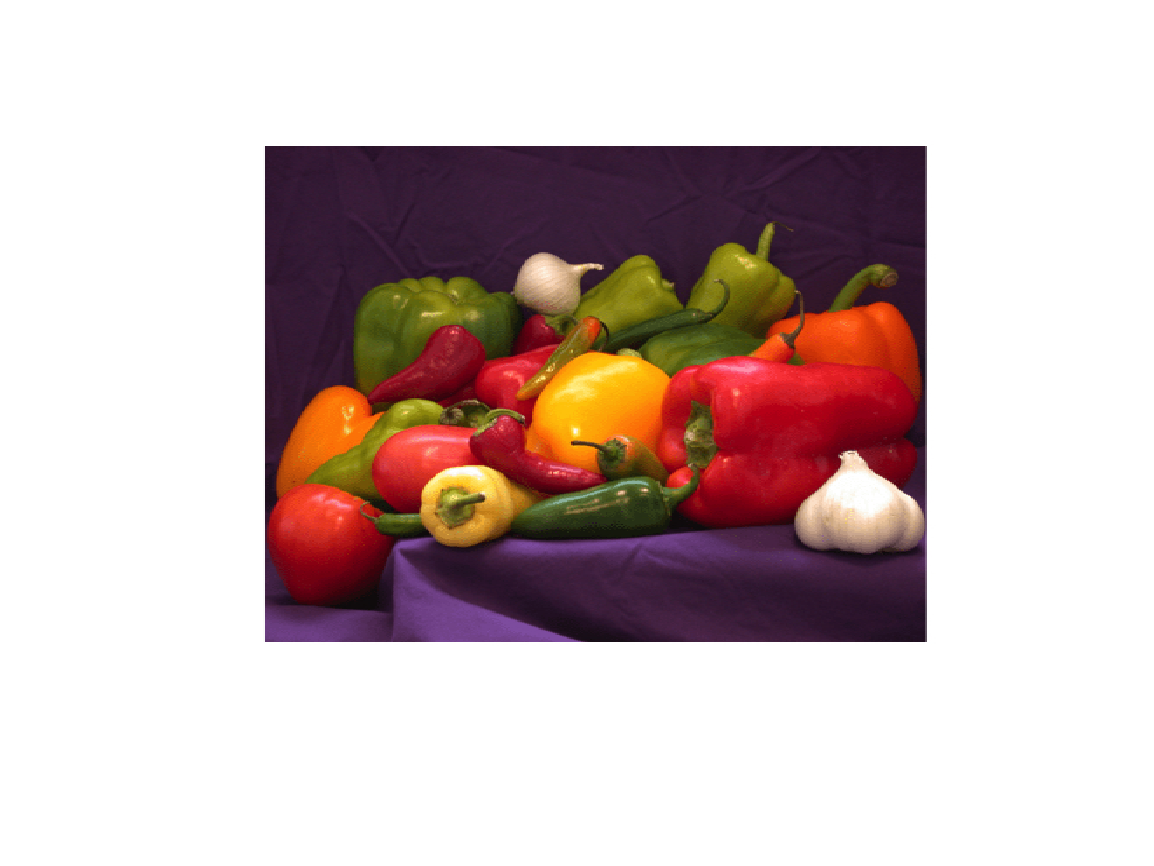

gooNet = googlenet;
Gnet = layerGraph(gooNet);
Gnet = removeLayers(Gnet,Gnet.Layers(end).Name);
dlGnet = dlnetwork(Gnet);
Gclasses = categories(gooNet.Layers(end).Classes);
testimg = imread("GenerateAdversarialExamplesExample/bellPepper.jpg");

figure
imshow(testimg)

**This section preprocesses the image to meet the network's requirements and tells the ground truth (GT)**

inputSize = gooNet.Layers(1).InputSize(1:2);
testrsz = imresize(testimg,inputSize);
[pred, proba] = classify(gooNet,testrsz);
GT = pred

GT = categorical
     bell pepper 



% One hot encoding based on the target class (one vs rest)
x = dlarray(single(testrsz),"SSCB");
GT = onehotencode(GT,1,"ClassNames",Gclasses);
GT = dlarray(single(GT),"CB");

**The ground truth came out to be "bell pepper"**

### **This section shows the implementation of *****untargeted***** adversarial attack using FGSM**

Create an adversarial example using the untargeted FGSM [3]. This method calculates the gradient $\nabla_X L\left(X,T\right)$ of the loss function $L$, with respect to the image $X$ you want to find an adversarial example for, and the class label $T$. This gradient describes the direction to "push" the image in to increase the chance it is misclassified. You can then add or subtract a small error from each pixel to increase the likelihood the image is misclassified. 

The adversarial example is calculated as follows:

$X_{\textrm{adv}} =X+\epsilon \ldotp \textrm{sign}\left(\nabla_X L\left(X,T\right)\right)$.

Parameter $\epsilon$ controls the size of the push. A larger $\epsilon$ value increases the chance of generating a misclassified image, but makes the change in the image more visible. This method is untargeted, as the aim is to get the image misclassified, regardless of which class.

Calculate the gradient of the image with respect to the golden retriever class.

grad = dlfeval(@untargetedGradients,dlGnet,x,GT);
eps = 5;
x_adv = x + eps*sign(grad);

ypred = predict(dlGnet,x);
ypred = onehotdecode(squeeze(ypred),Gclasses,1)

ypred = categorical
     bell pepper 



ypredAdv = predict(dlGnet,x_adv);
ypredAdv = onehotdecode(squeeze(ypredAdv),Gclasses,1)

ypredAdv = categorical
     matchstick 


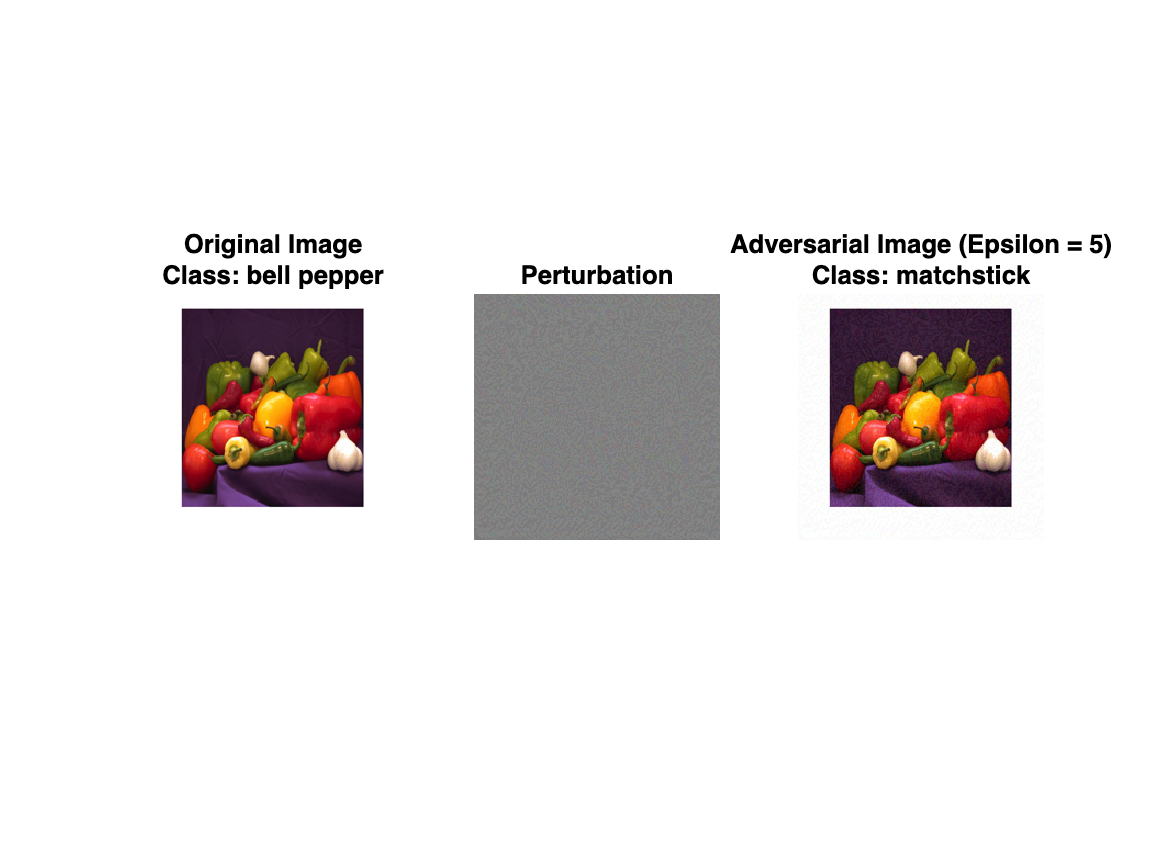

showAdversarialImage(x,ypred,x_adv,ypredAdv,eps)

We can see that the **bell pepper has been classified as a matchstick**, which is something we never mentioned in the first place but is definitely off the target.

### **This section shows the implementation of t*****argeted***** adversarial attack using BIM**

A simple improvement to FGSM is to perform multiple iterations. This approach is known as the basic iterative method (BIM) [4] or projected gradient descent [5]. For the BIM, the size of the perturbation is controlled by parameter $\alpha$ representing the step size in each iteration. This is as the BIM usually takes many, smaller, FGSM steps in the direction of the gradient. After each iteration, clip the perturbation to ensure the magnitude does not exceed $\epsilon$. This method can yield adversarial examples with less distortion than FGSM. 

When you use untargeted FGSM, the predicted label of the adversarial example can be very similar to the label of the original image. For example, a dog might be misclassified as a different kind of dog. However, you can easily modify these methods to misclassify an image as a specific class. Instead of maximizing the cross-entropy loss, you can minimize the mean squared error between the output of the network and the desired target output.

Generate a targeted adversarial example using the BIM and a cucumber target class.


Gtarget = "cucumber";
Gtarget = onehotencode(Gtarget,1,"ClassNames",Gclasses);

del = zeros(size(x),'like',x);
epsTar = 50;
alphaTar = 0.5;
numIter = 100;

for i = i:numIter
    grads = dlfeval(@targetedGradients,dlGnet,x,Gtarget);

    del = del - alphaTar*sign(grads);
    del(del > epsTar) = epsTar;
    del(del < -epsTar) = -epsTar;
end   

x_advTar = x + del;

ypredAdv_Tar = predict(dlGnet,x_advTar);
ypredAdv_Tar = onehotdecode(squeeze(ypredAdv_Tar),Gclasses,1)

ypredAdv_Tar = categorical
     cucumber 


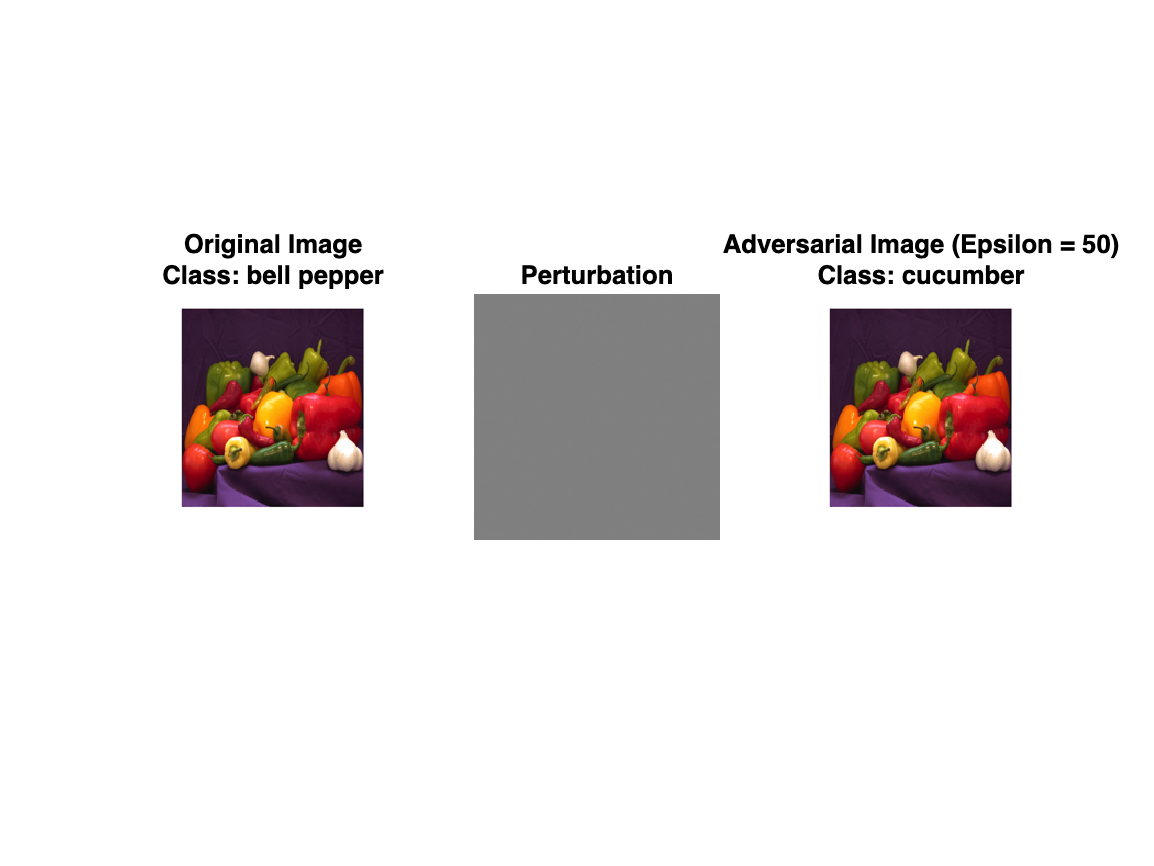


showAdversarialImage(x, ypred,x_advTar,ypredAdv_Tar,epsTar)

**Bell pepper has been classified as cucumber. **Hence, with a slight adjustment to the values of epsilon and alpha, we can clearly observe that we can achieve the intended target.

## Supporting Functions

### Untargeted Input Gradient Function

Calculate the gradient used to create an untargeted adversarial example. This gradient is the gradient of the cross-entropy loss.

function gradient = untargetedGradients(dlnet,X,target)

Y = predict(dlnet,X);
Y = stripdims(squeeze(Y));
loss = crossentropy(Y,target,'DataFormat','CB');
gradient = dlgradient(loss,X);

end

### Targeted Input Gradient Function

Calculate the gradient used to create a targeted adversarial example. This gradient is the gradient of the mean squared error.

function gradient = targetedGradients(dlnet,X,target)

Y = predict(dlnet,X);
Y = stripdims(squeeze(Y));
loss = mse(Y,target,'DataFormat','CB');
gradient = dlgradient(loss,X);

end

### Show Adversarial Image

Show an image, the corresponding adversarial image, and the difference between the two (perturbation).

function showAdversarialImage(image,label,imageAdv,labelAdv,epsilon)

figure
subplot(1,3,1)
imgTrue = uint8(extractdata(image));
imshow(imgTrue)
title("Original Image" + newline + "Class: " + string(label))

subplot(1,3,2)
perturbation = uint8(extractdata(imageAdv-image+127.5));
imshow(perturbation)
title("Perturbation")

subplot(1,3,3)
advImg = uint8(extractdata(imageAdv));
imshow(advImg)
title("Adversarial Image (Epsilon = " + string(epsilon) + ")" + newline + ...
    "Class: " + string(labelAdv))
end

## References

[1] Goodfellow, Ian J., Jonathon Shlens, and Christian Szegedy. “Explaining and Harnessing Adversarial Examples.” Preprint, submitted March 20, 2015. https://arxiv.org/abs/1412.6572.

[2] *ImageNet*. http://www.image-net.org.

[3] Szegedy, Christian, Wojciech Zaremba, Ilya Sutskever, Joan Bruna, Dumitru Erhan, Ian Goodfellow, and Rob Fergus. “Intriguing Properties of Neural Networks.” Preprint, submitted February 19, 2014. https://arxiv.org/abs/1312.6199.

[4] Kurakin, Alexey, Ian Goodfellow, and Samy Bengio. “Adversarial Examples in the Physical World.” Preprint, submitted February 10, 2017. https://arxiv.org/abs/1607.02533.

[5] Madry, Aleksander, Aleksandar Makelov, Ludwig Schmidt, Dimitris Tsipras, and Adrian Vladu. “Towards Deep Learning Models Resistant to Adversarial Attacks.” Preprint, submitted September 4, 2019. https://arxiv.org/abs/1706.06083.

*Copyright 2020 The MathWorks, Inc.*